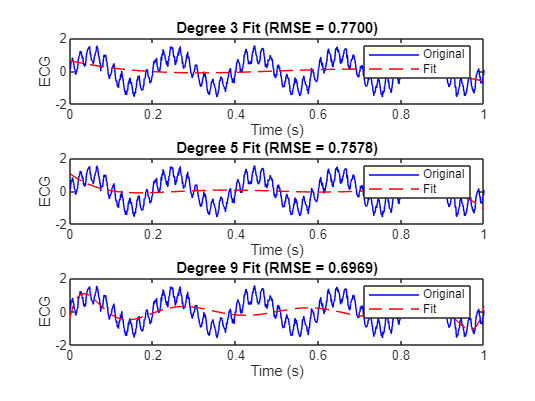

% 1b: Polynomial regression fitting
load('ECG_Data.mat');

t = linspace(0, 1, 1000);
signal = ECG(1, :);
degrees = [3, 5, 9];
rmses = zeros(1, 3);

figure;
for i = 1:length(degrees)
    p = polyfit(t, signal, degrees(i));
    fit_signal = polyval(p, t);
    
    rmses(i) = sqrt(mean((signal - fit_signal).^2));
    
    subplot(3,1,i);
    plot(t, signal, 'b'); hold on;
    plot(t, fit_signal, 'r--');
    title(sprintf('Degree %d Fit (RMSE = %.4f)', degrees(i), rmses(i)));
    xlabel('Time (s)'); ylabel('ECG'); legend('Original', 'Fit');
end


% Display RMSEs
fprintf('1b Polynomial Fit RMSEs:\n');

1b Polynomial Fit RMSEs:


for i = 1:3
    fprintf('Degree %d: RMSE = %.4f\n', degrees(i), rmses(i));
end

Degree 3: RMSE = 0.7700
Degree 5: RMSE = 0.7578
Degree 9: RMSE = 0.6969
